# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL -  A.Y. 2024/2025

# Full Examination

**July 18, 2025**

# Part 2 - Design of a Controller 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

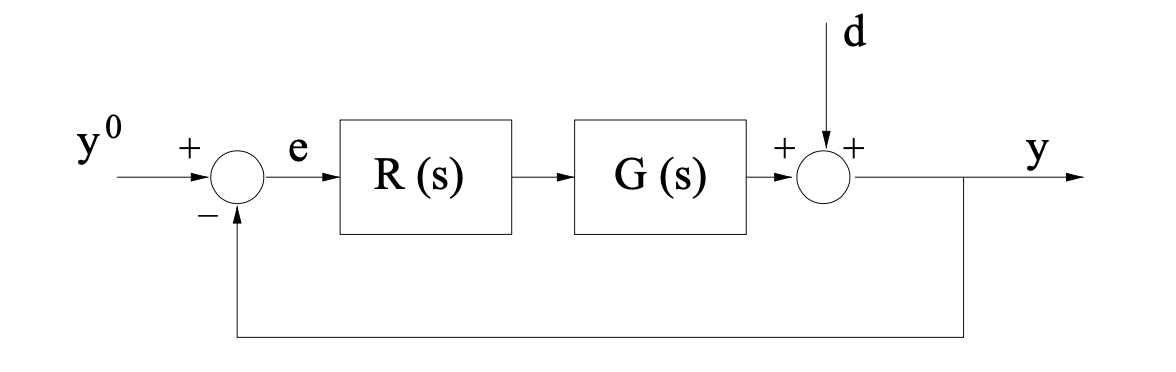	

where $G(s)$ is given by                


$$G(s) = \frac{1}{25}\,\frac{(1+3\,s)\,\left(1+\frac{s}{275}\right)}{\left(1+\frac{1}{50}\,s+\frac{s^2}{400} \right)\,\left(1+\frac{s}{297} \right)}$$


## **Question**	

**Q1**: Design a **proper** **controller** $C(s) = \mu_C\,\frac{1+s\,T}{s}\;,\quad \mu_C>0\,,\; T>0$ such that all following requirements are simultaneously met: 

- Zero steady-state error in unit step response (closed-loop) $e(\infty) =0$, when $d(t) =0\;\forall t$


$$ \begin{array}{rcl}
y^o(t) &=& 1(t) \\
\end{array}  \quad \Longrightarrow \quad e_{\infty} = 0
$$


            where $\mathbf{1}(t)$ denotes the unit step function;

- phase margin greater than or equal to $60^\circ$: $\varphi_m \ge 60^{\circ}$;

- For $d(t)=D \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall D \in \mathbb{R}, \; D>0$, $\omega \in \left[4\,,\; 28\right]\;\text{rad/s}$, the corresponding steady-state output $y_{d,\,\infty}(t)$ generated by the disturbance $d(t)$, with $y^o(t)=0$ $\forall t$ has magnitude satisfying $|y_{d,\,\infty}(t)| \le D/120$;

### Hint

How to handle the requirement on the disturbance $d(t)$ ? Recall the analysis we performed in Part 9 of the material (**Part 9**, **p. 48, 59** ), in Part 10 (**Part 10**, **p. 5 **),  and the example [DESIGN_REQS_D_N](https://units.sharepoint.com/:f:/r/sites/PATC_CD2024_IN03_034IN_395497/Class%20Materials/MATLAB_LIVE-SCRIPTS/Part_10/CONTROLLER_DESIGN_EXAMPLES_with_SOLUTIONS/DESIGN_REQS_D_N?csf=1&web=1&e=vYOi3F), available in the file repository part of the MS Teams course team.	

## Soluzione

clear
syms T mu_r
addpath(genpath('BodeDiagram/'));

Definizione della funzione di trasferimento $G(s)
$

s = tf('s');
G = (1/25)*(1+3*s)*(1+s/275) ...
    / ((1+s/50+s^2/400)*(1+s/297));

**2. Esplicitazione dei requisiti**

Il controllore $R(s)=\mu_R\frac{1+Ts}{s}$ deve soddisfare simultaneamente:

- Errore a regime nullo al gradino di riferimento ⇒ servono un polo in s=0s=0s=0 (integratore).

- Margine di fase $\varphi_m \ge 60\degree $ ⇒ robustezza rispetto a ritardi e variazioni del modello.

- Reiezione del disturbo d(t)=Dsin (ωt)d(t)=D\sin(\omega t)d(t)=Dsin(ωt) in uscita, per $\omega\in[4,28]$  rad/s:la funzione di sensibilità  $S(s)=\frac{1}{1+L(s)}$� deve soddisfare $|S(j\omega)|\le\frac{1}{120}$�.

**3. Analisi preliminare di **$G(s)$

Per individuare le frequenze critiche e valutare la necessità di un "boost" di fase, tracciamo il Bode di $G(s)$. Osservo:

- Dove il modulo di $G(s)$ si avvicina a 0 dB (punto di crossover naturale),

- Quanta fase manca intorno a quel punto per raggiungere almeno 60° di margine.

drawBodediagrams(G)

**4. Scelta della struttura del controllore**

Per garantire $e(\infty)=0$ (errore nullo) e $\varphi \ge 60\degree $, usiamo un PI:


$$R_0(s)=\frac{1+T\,s}{s},\qquad R(s)=\mu_R\,R_0(s)$$


Il polo in $s=0$ assicura l'integratore.

Lo zero in $s=-1/T$ introduce fino a $+90\degree $ di fase.

Il guadagno $\mu_R$ fissa il crossover e pertanto il margine.

**5. Sintesi numerica di **$T$** e **$\mu_R$**�**

Definiamo la banda di frequenze del disturbo $\omega_d\in[4,28]$ rad/s. Vogliamo che per tutte queste $\omega$:$|L(j\omega)| \;=\; |\mu_R\,R_0(j\omega)\,G(j\omega)| \;\ge\; 120$

Inoltre imponiamo $\varphi_m=60\degree $. Procediamo così:

- Costruiamo una griglia di candidati per $T$ (ad esempio da 0.01 s a 10 s).

- Per ciascun $T$, definiamo $R_0$� e calcoliamo $L_0=R_0\,G$.

- Troviamo $\mu$ risolvendo $\mathrm{margin}(\mu\,L_0)=60\degree $ via `fzero`.

- Verifichiamo che $\mu\,L_0(j\omega)\ge120$ per ogni $\omega$nella banda [4,28].

- Fermiamoci alla prima coppia $(T,\mu)$ che soddisfa entrambe le condizioni.

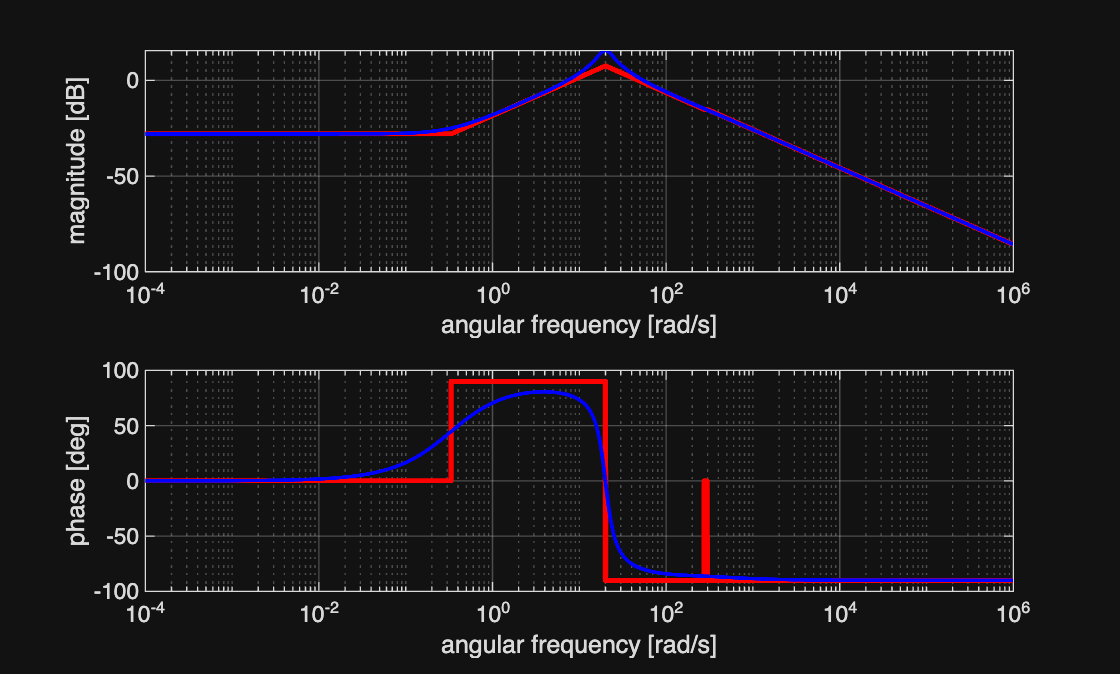

T_cand  = logspace(-2,1,40);    % T tra 0.01 e 10 s
mu_cand = logspace(-1,3,200);   % μ tra 0.1 e 1000
omega_d = logspace(log10(4),log10(28),200);

for T_try = T_cand
    R0 = (1 + T_try*s)/s;
    L0 = R0 * G;
    
    for mu_try = mu_cand

        L = mu_try * L0;
        % Calcolo margine di fase
        [~, Pm] = margin(L);    % Pm in gradi
        
        if Pm < 60
            continue             % non soddisfa il margine, provo altro μ
        end
        
        % Verifico reiezione disturbo: |L(jω)| ≥ 120
        mags = abs(squeeze(freqresp(L, omega_d)));
        if all(mags >= 120)
            % Ho trovato T e μ che funzionano
            T   = T_try;
            mu_R = mu_try;
            break               % esco dal ciclo mu
        end
    end
    
    if exist('mu_R','var')
        break                   % esco anche dal ciclo T
    end
end

**6. Verifica finale**

Ora che abbiamo $\mu_R$ e $T$, controlliamo i margini e la reiezione del disturbo:

- **Margine di fase** e **crossover** di $L=R\,G$

- **Modulo di **$S=\frac{1}{(1+L)$ sulla banda [4,28].

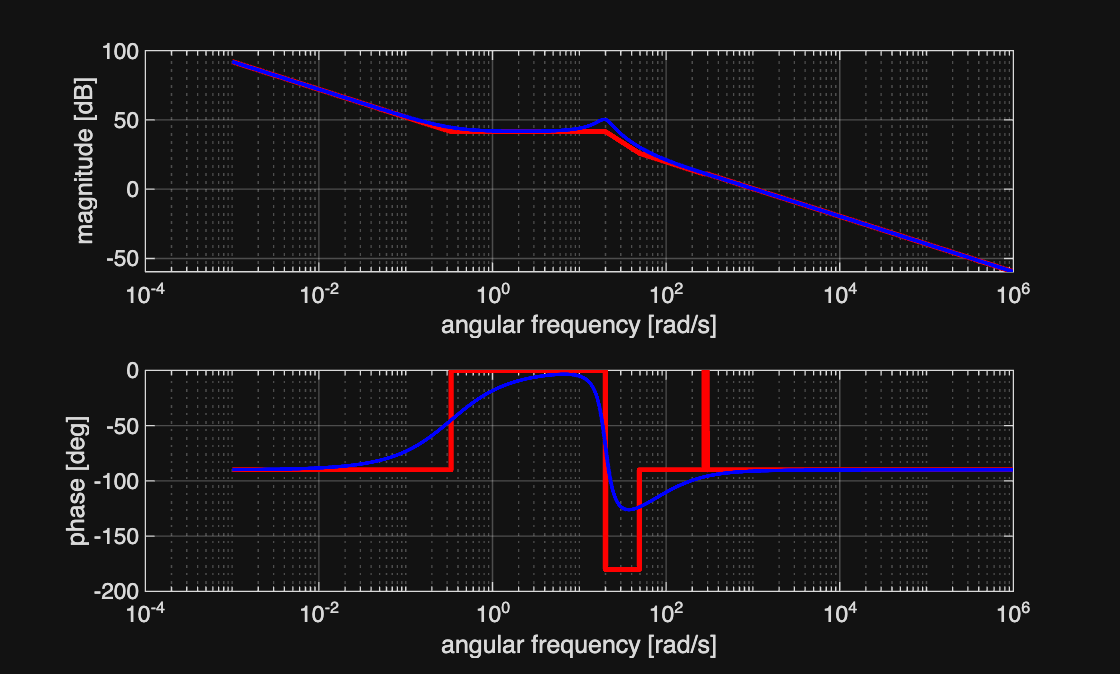

Output argument "haxMAG" (and possibly others) not assigned a value in the execution with "drawBodediagrams" function.

R = mu_R*(1+T*s)/s;
L = R * G;
S = 1/(1+L);

BD_L = drawBodediagrams(L)

% Reiezione disturbo
mS = abs(squeeze(freqresp(S, omega_d)));
fprintf('Max |S| in [4,28] = %.4f  (deve ≤ 1/120 = %.4f)\n', max(mS), 1/120)

display(mu_R)